# Design Cooling System 

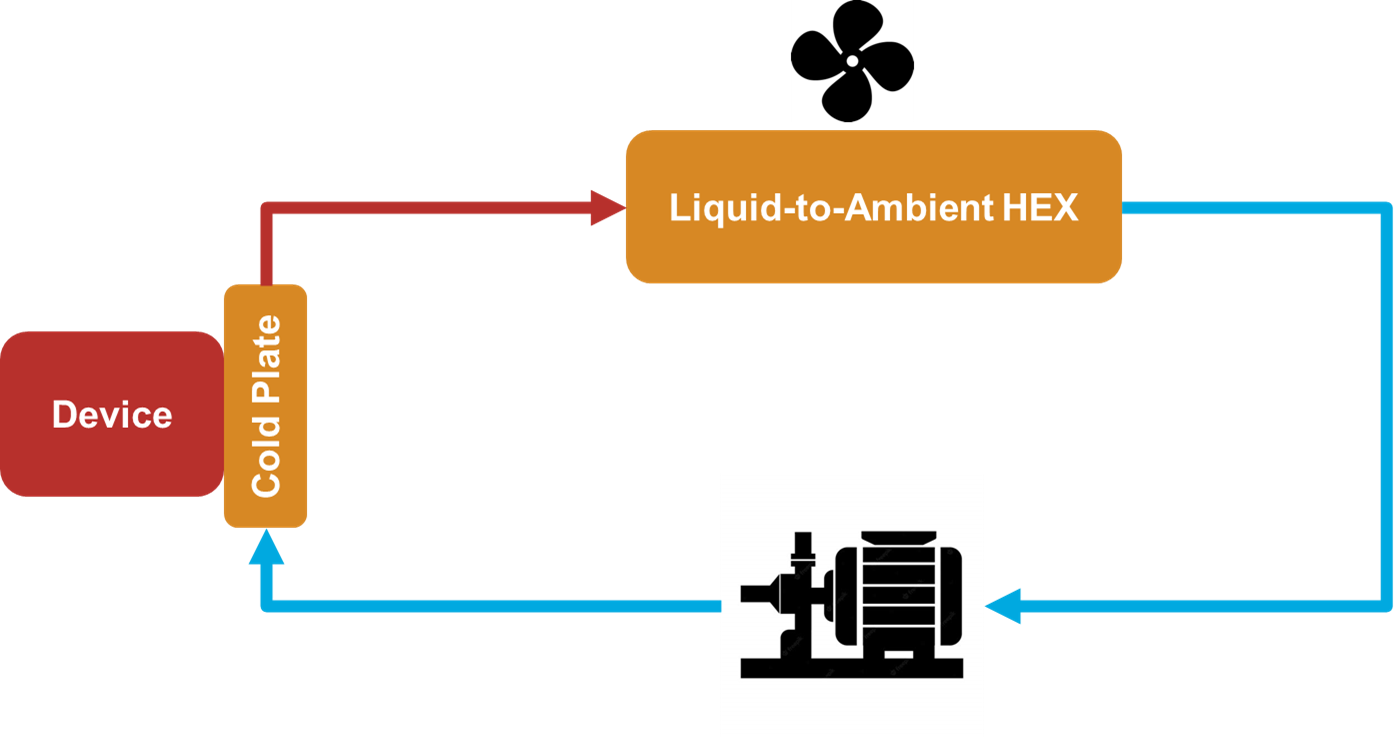

### Requirements for X-Ray Tube Cooling

- Remove up to 2 kW 

- Allowed coolant temperature rise 5°C

- Temperature set point: 25°C

- Device temperature should not exceed 50°C

- Working fluid: Water

- Working fluid pressurized at 2 bar

- Temperature stability +/- n°C

- Operating conditions: Inside at room temperature Tout must ot excess 30°C 

#### Requirements and operating conditions

QDiss           = 2000;         % (W) Heat load
deltaTCoolant   = 5;            % (°C) Maximum temperature rise allowed
TCoolantIn      = 25;           % (°C) Assumed coolant inlet temperature
TCoolantOutMax  = 30;           % (°C) Maximum coolant outlet temperature
TSurfaceMax     = 50;           % (°C) Maximum device temperature
TAmbient        = 20;           % (°C) Ambient temperature
pLoop           = 2;            % (bar) Pressure in coolant loop

#### Water properties at 25°C

cpCoolant       = 4180.74;      % (J/(kg*K)) heat cpacity
rhoCoolant      = 997.137;      % (kg/m^3) density
muCoolant       = 8.89995e-4;   % Pa·s
kCoolant        = 0.607;        % W/(m*K)
PrCoolant       = 6.134;        % (1) Prandtl number

#### Air porperties at 20°C

cpAir           = 1006;         % (J/(kg*K)) heat cpacity
rhoAir          = 1.204;        % (kg/m^3) density
kinViscAir      = 15e-6;        % (m^2/s) kinematic viscosity
PrAir           = 0.71;         % (1) Prandtly number
kAir            = 0.026;        % W/(m*K) 

**For simulation testing**

VDotLPMVec      = 3:8;     % (lpm)

#### Cold Plate

#### Determine required flow rate at operating conditions

mDot    = QDot/(cpCoolant*deltaTCoolant); % (kg/s) Mass flow rate
VDot    = mDot/rhoCoolant;                % (m^3/s) Volumetric flow rate
VDotLPM = mDot/rhoCoolant*1000*60;        % (l/min) Volumetric flow rate

Test steady state cold plate outlet temperature for different flow rates at constant heat

% VDotLPMVec = 3:8;                                      % l/min
mDotVec    = VDotLPMVec*0.001/60*rhoCoolant;            % kg/s
TCoolantOutVec  = QDot./(mDotVec*cpCoolant)+TCoolantIn;

plot(VDotLPMVec,TCoolantOutVec)
xlabel('Flow rate [l/min]')
ylabel('T_{cp,out}, [°C]');
hold on

Verify in Simscape model 

Notes:

- Talk about "boundary conditions" (also downstream vs upstream)

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_TCoolantOut');
    simInp(i) = simInp(i).setModelParameter('StopTime','7200');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, "UseFastRestart","on");

[14-Aug-2025 16:33:38] Running simulations...
[14-Aug-2025 16:33:41] Completed 1 of 6 simulation runs
[14-Aug-2025 16:33:41] Completed 2 of 6 simulation runs
[14-Aug-2025 16:33:41] Completed 3 of 6 simulation runs
[14-Aug-2025 16:33:42] Completed 4 of 6 simulation runs
[14-Aug-2025 16:33:42] Completed 5 of 6 simulation runs
[14-Aug-2025 16:33:42] Completed 6 of 6 simulation runs


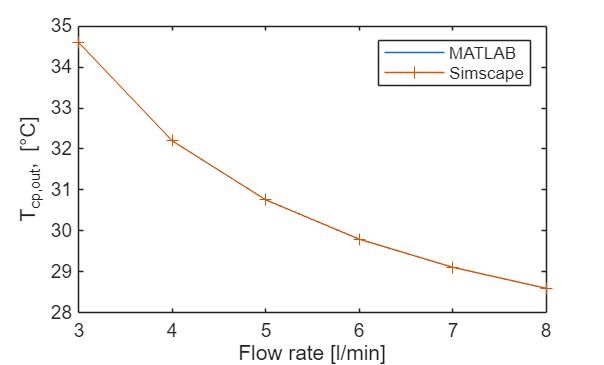


TCoolantOutVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    TCoolantOutTemp = simOut(i).simlog.Pipe_TL.B.T.series.values('degC');
    TCoolantOutVecSim(i) = TCoolantOutTemp(end);
end
clear TCoolantOutTemp simInp

plot(VDotLPMVec,TCoolantOutVecSim,'-+')
xlabel('Flow rate [l/min]')
ylabel('T_{cp,out}, [°C]');
legend('MATLAB','Simscape')
hold off

#### Cold plate resistance for maximum surface temperature at maximum coolant outlet temperature

Rcp = (TSurfaceMax - TCoolantOutMax)/QDot;   % K/W

Test resistance for different flow rates/outlet temperature 

mDotVec         = VDotLPMVec*0.001/60*rhoCoolant;    
TCoolantOutVec  = QDot./(mDotVec*cpCoolant)+TCoolantIn;

RcpVec = (TSurfaceMax - TCoolantOutVec)/QDot;   % K/W

figure
plot(TCoolantOutVec,RcpVec)
xlabel('T_{cp,out}, [°C]');
ylabel('R_{cp} [K/W]')

Verify in Simscape model

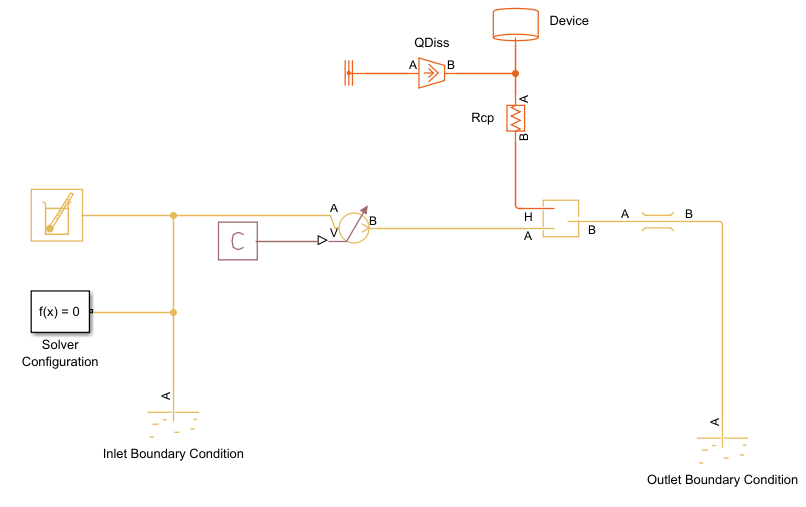

Notes:

- Talk about Chamber vs. Pipe

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_Rcp_Chamber');
    simInp(i) = simInp(i).setModelParameter('StopTime','7200');
    simInp(i) = simInp(i).setVariable('Rcp',RcpVec(i));
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp);

[14-Aug-2025 16:33:43] Running simulations...
[14-Aug-2025 16:33:47] Completed 1 of 6 simulation runs
[14-Aug-2025 16:33:48] Completed 2 of 6 simulation runs
[14-Aug-2025 16:33:49] Completed 3 of 6 simulation runs
[14-Aug-2025 16:33:50] Completed 4 of 6 simulation runs
[14-Aug-2025 16:33:52] Completed 5 of 6 simulation runs
[14-Aug-2025 16:33:53] Completed 6 of 6 simulation runs



TDeviceOutSim = zeros(size(VDotLPMVec));

for i = 1:numel(VDotLPMVec)
    TDeviceTemp = simOut(i).simlog.Device.M.T.series.values('degC');
    TDeviceOutSim(i) = TDeviceTemp(end);
end
clear TDeviceTemp  simInp
figure
plot(TCoolantOutVec,TDeviceOutSim,'-+')
xlabel('T_{cp,out}, [°C]');
ylabel('Device temperature [°C]')

**Size cold plate**

% Rcp goal = 0.01
% Example: Detector Cold Plate Spec Summary
% Material: Aluminum 167 W/m/K
% Size: 80 × 200 × 6 mm  
% Channels: Serpentine, 3.5 mm wide × 3 mm deep
% Channel length
% Wall thickness between channels >1mm
% Material thickness under channel floor >2mm

% Cold plate external dimensions
% Length 200-400 mm
% Width 100-300 mm
% Thickness 10-25 mm
% Surface area cold plate to X-Ray Tube
% Tube Diameter 50-120 mm
% Channel geometry
% Channel width 1-5 mm
% Channel depth 2-5 mm
% Channel pitch 2-10 mm
% Wall thickness 1-2 mmm
% Serpentine channels, channel length: 

cpL     = 250; % mm
cpW     = 150; % mm
deviceD = 75; % mm
cpDeviceSurfaceArea = pi*(deviceD/1000/2)^2; % m^2
cpK         = 167; % W/(mÜK)
cpThickness = 7; % mm

channelWidth     = 5; % mm
channelHeight    = 5;   % mm
channelPitch     = 10; % mm
effFlowLength    = 220; % mm
numPasses        = 14; % number of channel passes 
numChannels      = 1;
channelLength    = numPasses*effFlowLength/1000*numChannels; % m 
channelArea      = channelHeight*channelWidth; % mm^2
channelDh        = 2*channelWidth*channelHeight/(channelHeight+channelWidth); % mm
channelRoughness = 15e-6; % m


Test Rcp for given cold plate for different flow rates in Simscape model 

% VDotLPMVec = 3:8;                    % l/min

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_ColdPlate');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp,UseFastRestart="on");

[14-Aug-2025 16:33:55] Running simulations...
[14-Aug-2025 16:33:59] Completed 1 of 6 simulation runs
[14-Aug-2025 16:33:59] Completed 2 of 6 simulation runs
[14-Aug-2025 16:34:00] Completed 3 of 6 simulation runs
[14-Aug-2025 16:34:00] Completed 4 of 6 simulation runs
[14-Aug-2025 16:34:00] Completed 5 of 6 simulation runs
[14-Aug-2025 16:34:00] Completed 6 of 6 simulation runs


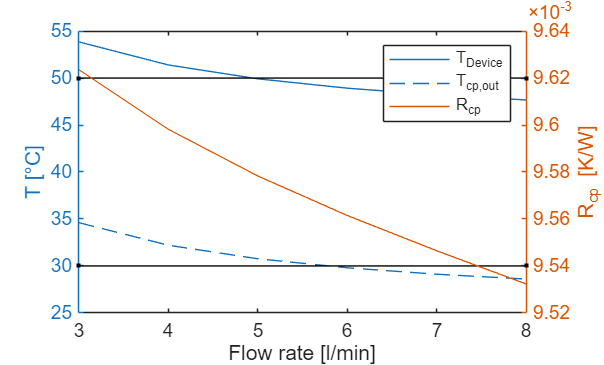


TDeviceOutSim  = zeros(size(VDotLPMVec));
TCoolantOutSim = zeros(size(VDotLPMVec));

for i = 1:numel(VDotLPMVec)
    TDeviceTemp = simOut(i).simlog.Device.M.T.series.values('degC');
    TDeviceOutSim(i) = TDeviceTemp(end);
    TCoolantOutTemp = simOut(i).simlog.Pipe_TL.B.T.series.values('degC');
    TCoolantOutSim(i) = TCoolantOutTemp(end);    
end

clear TDeviceTemp  TCoolantOutTemp simInp

RcpSim = (TDeviceOutSim-TCoolantOutSim)/QDot;

figure
yyaxis left
plot(VDotLPMVec,TDeviceOutSim,VDotLPMVec,TCoolantOutSim);
hold on 
plot([VDotLPMVec(1),VDotLPMVec(end)],[TCoolantOutMax,TCoolantOutMax],'k.-')
plot([VDotLPMVec(1),VDotLPMVec(end)],[TSurfaceMax,TSurfaceMax],'k.-')

ylabel('T [°C]')

yyaxis right
plot(VDotLPMVec, RcpSim);
ylabel('R_{cp} [K/W]')

xlabel('Flow rate [l/min]')
legend('T_{Device}','T_{cp,out}','','','R_{cp}')

hold off

#### Determine pressure drop in cold plate

% Reynolds number
Re              = mDot*channelDh*1e-3/(channelArea*1e-6*muCoolant);
shapeFactor     = 64;

% Darcy friction factor 
friction = 1 / (-1.8 * log10(6.9/Re + (channelRoughness/(channelDh*1e-3)/3.7)^1.11))^2; % Turbulent flow - Haaland correlation

% Laminar pressure drop
deltaPCPLam  =  mDot*muCoolant*shapeFactor*channelLength/(2*rhoCoolant*(channelDh*1e-3)^2*channelArea*1e-6);        % (Pa)
% Turbulent pressure drop
deltaPCPTurb = friction*mDot^2*channelLength/(2*rhoCoolant*channelDh*1e-3*(channelArea*1e-6)^2);       % Pa

% Pressure drop (not accounting for temperature differences)
deltaPCP = blend(deltaPCPLam,deltaPCPTurb,2000,4000,Re);


Test pressure drop for different flow rates 

mDotVec    = VDotLPMVec*0.001/60*rhoCoolant;  % kg/s
ReVec      = mDotVec*channelDh*1e-3/(channelArea*1e-6*muCoolant);

% Darcy friction factor 
frictionVec = 1 ./ (-1.8 * log10(6.9./ReVec + (channelRoughness/(channelDh*1e-3)/3.7)^1.11)).^2; % Turbulent flow - Haaland correlation

% Laminar pressure drop
deltaPCPLamVec  =  mDotVec*muCoolant*shapeFactor*channelLength/(2*rhoCoolant*(channelDh*1e-3)^2*channelArea*1e-6);        % (Pa)
% Turbulent pressure drop
deltaPCPTurbVec = frictionVec.*mDotVec.^2*channelLength./(2*rhoCoolant*channelDh*1e-3*(channelArea*1e-6)^2);              % (Pa)

% Pressure drop (not accounting for temperature differences)
deltaPCPVec = blend(deltaPCPLamVec,deltaPCPTurbVec,2000,2001,ReVec);  % Pa

figure
plot(VDotLPMVec,deltaPCPVec/1e6)
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
hold on

Test in Simscape model 

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_deltaP_ColdPlate');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[14-Aug-2025 16:34:03] Running simulations...
[14-Aug-2025 16:34:06] Completed 1 of 6 simulation runs
[14-Aug-2025 16:34:06] Completed 2 of 6 simulation runs
[14-Aug-2025 16:34:06] Completed 3 of 6 simulation runs
[14-Aug-2025 16:34:06] Completed 4 of 6 simulation runs
[14-Aug-2025 16:34:06] Completed 5 of 6 simulation runs
[14-Aug-2025 16:34:06] Completed 6 of 6 simulation runs


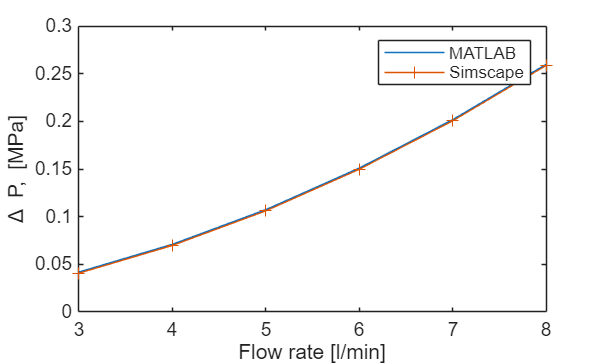


deltaPCPVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    pATemp = simOut(i).simlog.Pipe_TL.A.p.series.values('Pa');
    pBTemp = simOut(i).simlog.Pipe_TL.B.p.series.values('Pa');
    deltaPCPVecSim(i) = pATemp(end)-pBTemp(end);
end
clear pATemp pBTemp simInp

plot(VDotLPMVec,deltaPCPVecSim/1e6,'-+')
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
legend('MATLAB','Simscape')
hold off

#### Size the radiator

% Single pass cross flow HEX
% Air enters at ambient temperatre
% Fan creates air flow of 0.8 m^3/s 
% Coolant radiator inlet temperature (max cold plate outlet temperature) : 30°C
% Coolant radiator outlet temperature (desired cold plate inlet temperature): 25°C
% Coolant flow rate (nominal): VDotLPM

VDotAir    = 0.8; % (m^3/s) Assumed air flow rate
mDotAir    = VDotAir*rhoAir; % kg/s 
% hAir       = 100; % W/(m^2*K) Assumed heat transfer coefficient air side
% TAirOut    = 23;    % (°C) Assumed air outlet temperature

% Size
HEXCoreL = 350; % mm
HEXCoreH = 350; % mm
HEXCoreW = 88;  % mm
HEXTubeW = 88; % mm
HEXTubeH = 2; %mm
HEXTubeL = 350; % mm

HEXTubeWOuter = HEXTubeW+1; % mm
HEXTubeHOuter = HEXTubeH+1; % mm

tubesCrossArea = HEXTubeW*HEXTubeH; % mm


numTubes = 16;

areaOuterTubes = numTubes*2*(HEXTubeWOuter+HEXTubeHOuter*0)*HEXTubeL; % mm^2
areaInnerTubes = numTubes*2*(HEXTubeW+HEXTubeH)*HEXTubeL; % mm^2
DhTubes = 2*HEXTubeW*HEXTubeH/(HEXTubeW+HEXTubeH); % mm

tubeRoughness = 15e-6;  % m

finEfficiency = 0.75;
finSpacing = 2; % mm
gapHTubes = (HEXCoreH - numTubes*HEXTubeH)/(numTubes - 1); % mm
areaAirFlow = (numTubes - 1)*HEXCoreH*gapHTubes; % mm^2
numFins = (numTubes-1)*HEXCoreL/finSpacing;
areaAirFins = 2*numFins*HEXCoreW*gapHTubes; % mm^2


areaAirTotal = (areaAirFins*finEfficiency+areaOuterTubes)/1e6;

Test in Simscape model for different thermal liquid flow rates

% VDotLPMVec = 3:8;                    % l/min

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_Radiator');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[14-Aug-2025 16:34:08] Running simulations...
[14-Aug-2025 16:34:19] Completed 1 of 6 simulation runs
[14-Aug-2025 16:34:19] Completed 2 of 6 simulation runs
[14-Aug-2025 16:34:19] Completed 3 of 6 simulation runs
[14-Aug-2025 16:34:20] Completed 4 of 6 simulation runs
[14-Aug-2025 16:34:20] Completed 5 of 6 simulation runs
[14-Aug-2025 16:34:20] Completed 6 of 6 simulation runs


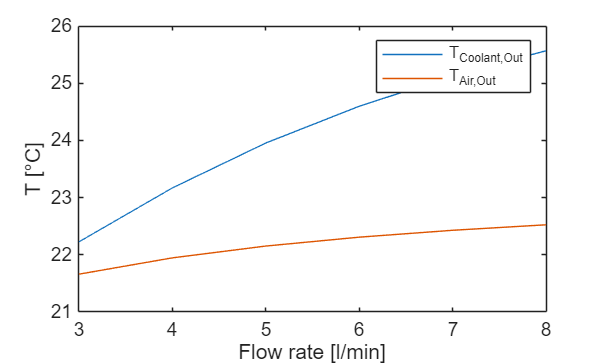


TCoolantOutVec = zeros(size(simInp));
TAirOutVec     = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    TCoolantOutTemp = simOut(i).simlog.Heat_Exchanger_TL_MA.B1.T.series.values('degC');
    TAirOutVecTemp  = simOut(i).simlog.Heat_Exchanger_TL_MA.B2.T.series.values('degC');
    TCoolantOutVec(i) = TCoolantOutTemp(end);
    TAirOutVec(i) = TAirOutVecTemp(end);
end
clear TCoolantOutTemp pBTemp simInp

plot(VDotLPMVec,[TCoolantOutVec',TAirOutVec'])
xlabel('Flow rate [l/min]')
ylabel('T [°C]');
legend('T_{Coolant,Out}','T_{Air,Out}')
hold off

#### Determine pressure drop in radiator 

% Reynolds number
% velRadiator     = VDot/(tubesCrossArea*1e-6);           % (m/s) Flow velocity
mDotRadiator    = VDot*rhoCoolant;                      % (kg/s)
Re              = mDotRadiator*DhTubes*1e-3/(tubesCrossArea*1e-6*numTubes*muCoolant);

% Interpolation for shape factor
xIn = [0 1/8 1/6 1/5 1/4 1/3 1/2 1];
yIn = [96.00 82.32 78.80 76.28 72.92 68.36 62.20 56.92];
xShapeFactor = min(HEXTubeW,HEXTubeH)/max(HEXTubeW,HEXTubeH);
shapeFactor    = interp1(xIn,yIn,xShapeFactor);

% Darcy friction factor 
frictionVec = 1 / (-1.8 * log10(6.9/Re + (tubeRoughness/(DhTubes*1e-3)/3.7)^1.11))^2; % Turbulent flow - Haaland correlation

% Laminar pressure drop
deltaPRadiatorLam  = mDotRadiator*muCoolant*shapeFactor*HEXTubeL*1e-3/(2*rhoCoolant*(DhTubes*1e-3)^2*tubesCrossArea*1e-6*numTubes); % (Pa)
% Turbulent pressure drop
deltaPRadiatorTurb = frictionVec*mDotRadiator^2*HEXTubeL*1e-3/(2*rhoCoolant*DhTubes*1e-3*(tubesCrossArea*1e-6*numTubes)^2);       % Pa


% Pressure drop blend between laminar and turbulent (not accounting for temperature differences)
deltaPRadiator = blend(deltaPRadiatorLam,deltaPRadiatorTurb,2000,4000,Re);





Pressure dop for different flow rates 

% VDotLPMVec      = 3:8;                                 % l/min
mDotRadiatorVec = VDotLPMVec*0.001/60*rhoCoolant; % kg/s
ReVec           = mDotRadiatorVec*DhTubes*1e-3/(tubesCrossArea*1e-6*numTubes*muCoolant);


% Darcy friction factor 
frictionVec = 1 ./ (-1.8 * log10(6.9./ReVec + (tubeRoughness/(DhTubes*1e-3)/3.7)^1.11)).^2; % Turbulent flow - Haaland correlation

% Laminar pressure drop
deltaPRadiatorLamVec  = mDotRadiatorVec.*muCoolant*shapeFactor*HEXTubeL*1e-3/(2*rhoCoolant*(DhTubes*1e-3)^2*tubesCrossArea*1e-6*numTubes); % (Pa)
% Turbulent pressure drop
deltaPRadiatorTurbVec = frictionVec.*mDotRadiatorVec.^2*HEXTubeL*1e-3/(2*rhoCoolant*DhTubes*1e-3*(tubesCrossArea*1e-6*numTubes)^2);       % Pa

% Pressure drop blend between laminar and turbulent (not accounting for temperature differences)
deltaPRadiatorVec = blend(deltaPRadiatorLamVec,deltaPRadiatorTurbVec,2000,4000,ReVec);

figure
plot(VDotLPMVec,deltaPRadiatorVec/1e6)
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
hold on

Test pressure dop in Simscape for different flow rates

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_deltaP_Radiator');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[14-Aug-2025 16:36:54] Running simulations...
[14-Aug-2025 16:37:06] Completed 1 of 6 simulation runs
[14-Aug-2025 16:37:07] Completed 2 of 6 simulation runs
[14-Aug-2025 16:37:07] Completed 3 of 6 simulation runs
[14-Aug-2025 16:37:08] Completed 4 of 6 simulation runs
[14-Aug-2025 16:37:09] Completed 5 of 6 simulation runs
[14-Aug-2025 16:37:09] Completed 6 of 6 simulation runs


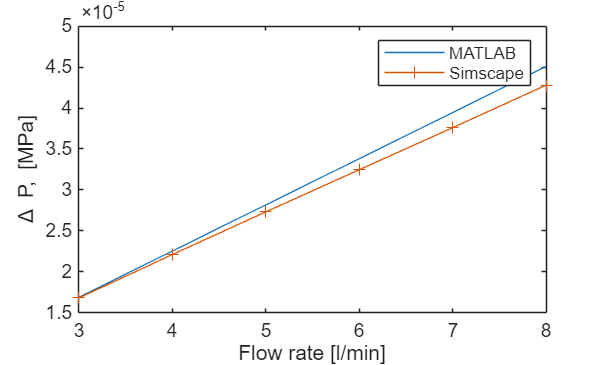


deltaPRadiatorVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    pATemp = simOut(i).simlog.Heat_Exchanger_TL_MA.A1.p.series.values('Pa');
    pBTemp = simOut(i).simlog.Heat_Exchanger_TL_MA.B1.p.series.values('Pa');
    deltaPRadiatorVecSim(i) = pATemp(end)-pBTemp(end);
end
clear pATemp pBTemp simInp

plot(VDotLPMVec,deltaPRadiatorVecSim/1e6,'-+')
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
legend('MATLAB','Simscape')
hold off

**Additional pressure losses**

% Accounting for additional pressure losses
% Assuming 2m of 10 mm diamater piping plus 1 m of equivalent length for
% additional components

pipingD = 10; % mm
pipingL = 2;  % m
pipingAddL = 1; % m
pipingArea = pi*(pipingD/2)^2; % mm^2
pipingRoughness = 15e-6;       % m

Test pressure loss for different flow rates in Simscape models

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_deltaP_Piping');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[14-Aug-2025 16:37:19] Running simulations...
[14-Aug-2025 16:37:25] Completed 1 of 6 simulation runs
[14-Aug-2025 16:37:25] Completed 2 of 6 simulation runs
[14-Aug-2025 16:37:26] Completed 3 of 6 simulation runs
[14-Aug-2025 16:37:26] Completed 4 of 6 simulation runs
[14-Aug-2025 16:37:27] Completed 5 of 6 simulation runs
[14-Aug-2025 16:37:27] Completed 6 of 6 simulation runs


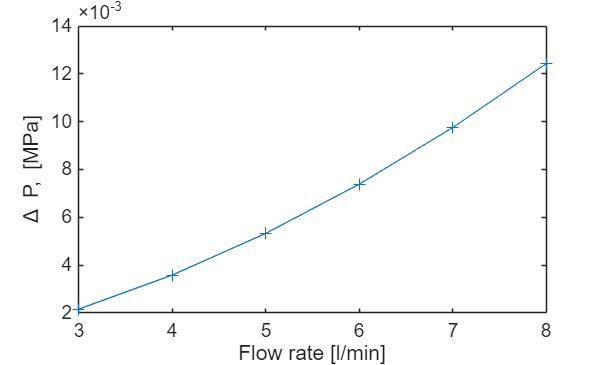


deltaPPipingVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    pATemp = simOut(i).simlog.Pipe_TL.A.p.series.values('Pa');
    pBTemp = simOut(i).simlog.Pipe_TL.B.p.series.values('Pa');
    deltaPPipingVecSim(i) = pATemp(end)-pBTemp(end);
end
clear pATemp pBTemp simInp

plot(VDotLPMVec,deltaPPipingVecSim/1e6,'-+')
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
hold off

#### Pump parameterization

pumpHead        = 15;   % m
pumpBrkPwr      = 26;   % W
pumpHeadRefMax  = 22;   % m
pumpCapZeroHead = 10;   % lpm
pumpRefSpeed    = 2900; % rpm
pumpInertia     = 1e-5; % kg*m^2

Test in Simscape model

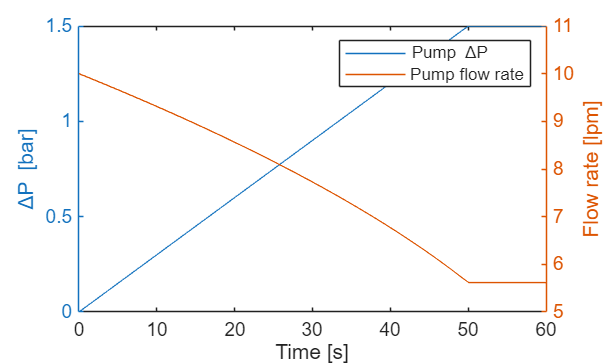

tInPumpTest     = [0;50;60];  % s
loadInPumpTest  = [0;1.5;1.5]; % bar

simInp = Simulink.SimulationInput('example_Pump');
simOut = sim(simInp);

figure
yyaxis left
plot(simOut.tout,simOut.simlog.Centrifugal_Pump_TL.p_diff.series.values('bar'));
ylabel('\DeltaP [bar]')
yyaxis right
plot(simOut.tout,simOut.simlog.Centrifugal_Pump_TL.q_A.series.values('lpm'));
ylabel('Flow rate [lpm]')
xlabel('Time [s]')
legend('Pump \DeltaP','Pump flow rate')
hold off

**Assemble and system - open loop**

pumpInpSpeed = 2900; % rpm
pumpInitSpeed = 0; % rpm
simInp = Simulink.SimulationInput('example_System_Assembly');
simOut = sim(simInp);

% Extract results
% Pump
VDotSim         = simOut.simlog.Pump.Centrifugal_Pump_TL.q_A.series.values('lpm');
% Devide
TDeviceSim      = simOut.simlog.ColdPlate.Device.M.T.series.values('degC');
% Cold plate
TCPInletSim     = simOut.simlog.ColdPlate.Pipe_TL.A.T.series.values('degC');
TCPOutletSim    = simOut.simlog.ColdPlate.Pipe_TL.B.T.series.values('degC');
pCPInletSim     = simOut.simlog.ColdPlate.Pipe_TL.A.p.series.values('bar');
pCPOutletSim    = simOut.simlog.ColdPlate.Pipe_TL.B.p.series.values('bar');
% Radiator
TRadiatorInletSim     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.T.series.values('degC');
TRadiatorOutletSim    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.T.series.values('degC');
pRadiatorInletSim     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.p.series.values('bar');
pRadiatorOutletSim    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.p.series.values('bar');
% Piping
pPipingInletSim     = simOut.simlog.Piping.Pipe_TL.A.p.series.values('bar');
pPipingOutletSim    = simOut.simlog.Piping.Pipe_TL.B.p.series.values('bar');

% Assemble table to display
Measurement         = ["VDot [lpm]";"T_Device [degC]";"T_cp,in [degC]";"T_cp,out [degC]";"T_rad,in [degC]";"T_rad,out [degC]";...
            "p_cp,in [bar]";"p_cp,out [bar]";"p_rad,in [bar]";"p_rad,out [bar]";"p_piping,in [bar]";"p_piping,out [bar]"];


MeasurementValues   = [VDotSim(end);TDeviceSim(end);TCPInletSim(end);TCPOutletSim(end);TRadiatorInletSim(end);TRadiatorOutletSim(end);...
    pCPInletSim(end);pCPOutletSim(end);pRadiatorInletSim(end);pRadiatorOutletSim(end);pPipingInletSim(end);pPipingOutletSim(end)];

outputTable = table(Measurement, MeasurementValues);
disp(outputTable)

        Measurement         MeasurementValues
    ____________________    _________________

    "VDot [lpm]"             5.7777120473449 
    "T_Device [degC]"       49.1477333137121 
    "T_cp,in [degC]"        25.0035274043356 
    "T_cp,out [degC]"       30.0180279390204 
    "T_rad,in [degC]"       30.0180279390204 
    "T_rad,out [degC]"      24.4786811488357 
    "p_cp,in [bar]"         3.46240321368916 
    "p_cp,out [bar]"        2.06959450061572 
    "p_rad,in [bar]"        2.06959450061572 
    "p_rad,out [bar]"       2.06919193252806 
    "p_piping,in [bar]"     2.06919193252806 
    "p_piping,out [bar]"                   2 



**Closed-loop system with accumulator**

pumpInpSpeed = 2900; % rpm
pumpInitSpeed = 0; % rpm
simInp = Simulink.SimulationInput('example_System_Assembly_ClosedLoop');
simOut = sim(simInp);

['example_System_Assembly_ClosedLoop/Gas-Charged Accumulator (TL)', 'example_System_Assembly_ClosedLoop/Perfect Insulator']: Each physical network must be connected to exactly one Solver Configuration block. There is no Solver Configuration block connected to Physical Network with the following blocks: 'example_System_Assembly_ClosedLoop/Gas-Charged
Accumulator (TL)'
'example_System_Assembly_ClosedLoop/Perfect Insulator'


% Extract results
% Pump
VDotSim         = simOut.simlog.Pump.Centrifugal_Pump_TL.q_A.series.values('lpm');
% Devide
TDeviceSim      = simOut.simlog.ColdPlate.Device.M.T.series.values('degC');
% Cold plate
TCPInletSim     = simOut.simlog.ColdPlate.Pipe_TL.A.T.series.values('degC');
TCPOutletSim    = simOut.simlog.ColdPlate.Pipe_TL.B.T.series.values('degC');
pCPInletSim     = simOut.simlog.ColdPlate.Pipe_TL.A.p.series.values('bar');
pCPOutletSim    = simOut.simlog.ColdPlate.Pipe_TL.B.p.series.values('bar');
% Radiator
TRadiatorInletSim     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.T.series.values('degC');
TRadiatorOutletSim    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.T.series.values('degC');
pRadiatorInletSim     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.p.series.values('bar');
pRadiatorOutletSim    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.p.series.values('bar');
% Piping
pPipingInletSim     = simOut.simlog.Piping.Pipe_TL.A.p.series.values('bar');
pPipingOutletSim    = simOut.simlog.Piping.Pipe_TL.B.p.series.values('bar');

% Assemble table to display
Measurement         = ["VDot [lpm]";"T_Device [degC]";"T_cp,in [degC]";"T_cp,out [degC]";"T_rad,in [degC]";"T_rad,out [degC]";...
            "p_cp,in [bar]";"p_cp,out [bar]";"p_rad,in [bar]";"p_rad,out [bar]";"p_piping,in [bar]";"p_piping,out [bar]"];

MeasurementValues   = [VDotSim(end);TDeviceSim(end);TCPInletSim(end);TCPOutletSim(end);TRadiatorInletSim(end);TRadiatorOutletSim(end);...
    pCPInletSim(end);pCPOutletSim(end);pRadiatorInletSim(end);pRadiatorOutletSim(end);pPipingInletSim(end);pPipingOutletSim(end)];

outputTable = table(Measurement, MeasurementValues);
disp(outputTable)

Notes:

Next steps:

- Pressure drop radiotor

- Pressure drop additional components

- Size Pump

- Pressurization

- Test harnesses for dynamic model

- Assemble everything in a loop

- For hotter conditions: evaporator

- Add pressurization